txdataF = [0, 1+j*1, 1+j*1, 0, 0]

txdataF =    0.0000 + 0.0000i   1.0000 + 1.0000i   1.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



txdata = ifft(txdataF, 5)

txdata =    0.4000 + 0.4000i  -0.4078 + 0.2078i  -0.0273 - 0.1727i  -0.1727 - 0.0273i   0.2078 - 0.4078i



txdataF_res = fft(txdata, 5)

txdataF_res =    0.0000 + 0.0000i   1.0000 + 1.0000i   1.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


% Carrier config
carrier = nrCarrierConfig;
carrier.SubcarrierSpacing = 15;
carrier.NSizeGrid = 106;

% Prach config
prach = nrPRACHConfig;
prach.FrequencyRange = 'FR1';   % Frequency range ('FR1', 'FR2')
prach.DuplexMode = 'FDD';       % Duplex mode ('FDD', 'TDD', 'SUL')
prach.ConfigurationIndex = 16; % Configuration index (0...255)
prach.SubcarrierSpacing = 1.25;   % Subcarrier spacing (1.25, 5, 15, 30, 60, 120)
prach.FrequencyIndex = 0; %n_RA       % Index of the PRACH transmission occasions in frequency domain (0...7)
prach.TimeIndex = 0; %n_t^RA        % Index of the PRACH transmission occasions in time domain (0...6)
prach.ActivePRACHSlot = 0;      % Active PRACH slot number within a subframe or a 60 kHz slot (0, 1)
prach.SequenceIndex = 1;


txdata;

tx = 	1.0e+02 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


txdataF_gNB;

txF = 	1.0e+03 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0010 + 0.0000i
   0.0000 + 0.0000i
  -0.0010 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


% txsig = tx(30721:30721+24576);
txsig = tx;
ofdmInfo = nrPRACHOFDMInfo(carrier,prach)

ofdmInfo = struct with fields:
                   Nfft: 24576
             SampleRate: 30720000
    CyclicPrefixLengths: 3168
           GuardLengths: 2976
          SymbolLengths: 30720
           OffsetLength: 0
              Windowing: 861


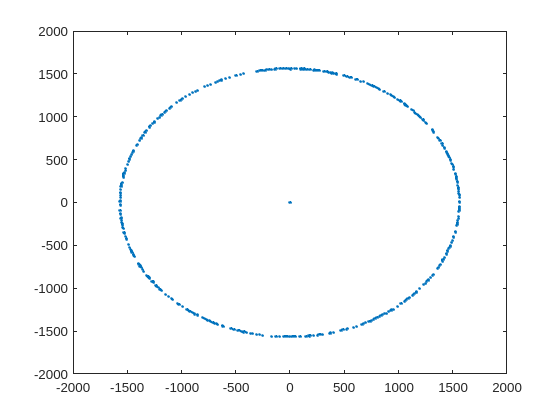

% nfft = ofdmInfo.Nfft;
nfft = 30720;

plot(txF, ".")

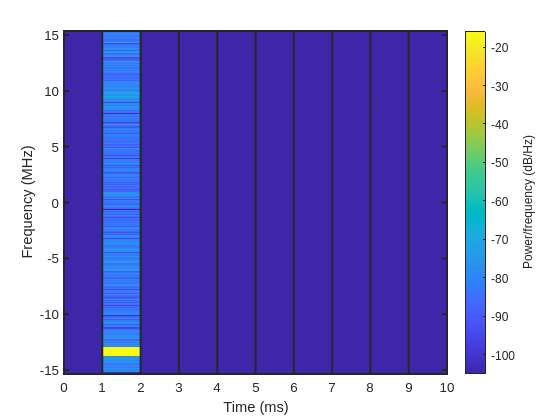


figure
spectrogram(txsig(:,1),ones(nfft,1),0,'centered',nfft,ofdmInfo.SampleRate, ...
    'yaxis','MinThreshold',-105);
grid on
set(gca, 'YGrid', 'off', 'XGrid', 'on', 'LineWidth', 1.5, 'GridAlpha', 1)
xticks(0:1:10)